Ejercicio 1:

I = imread('./Media/imatge2.jpg');
I = rgb2gray(I);
I = imnoise(I,'salt & pepper', 0.02);
I = double(I);
F = Ejercicio_1(I);

Tras la aplicacion del flitro de media aritmetica obtenemos una imagen 'blurred:

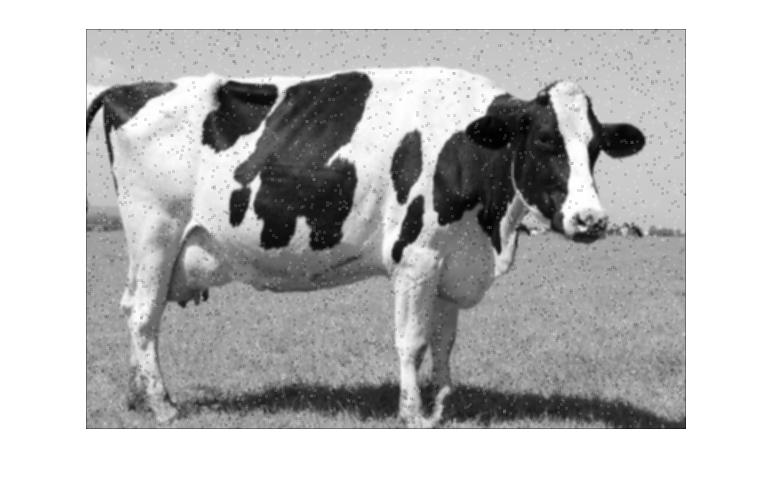

imshow(F, []);

Podemos comparar la imagen anterior con la aplicacion del filtro segun la implementacion de matlab, y como vemos, a pesar de haber realizado el filtro en 2 partes (primero verticalmente y luego horizontalmente), obtenemos el mismo resultado.

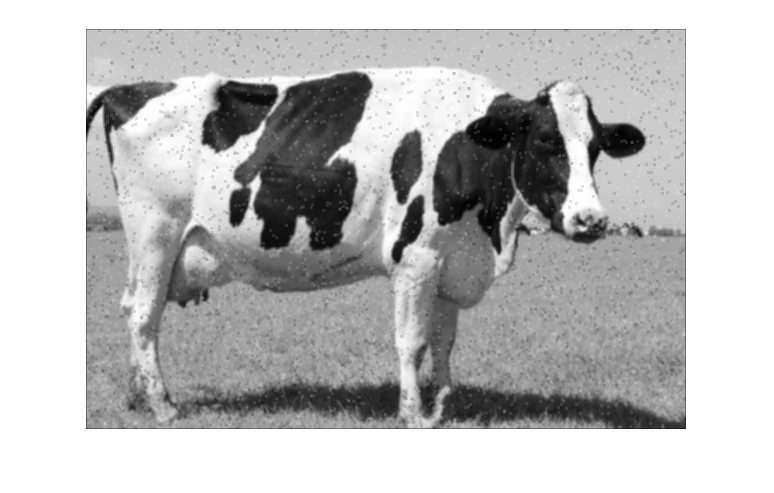

imshow(imfilter(I, fspecial('average',3)), []);

Ejercicio 2:

I = imread('./Media/imatge2.jpg');
I = rgb2gray(I);
I = imnoise(I,'salt & pepper', 0.02);
I = double(I);

Imagen con ruido:

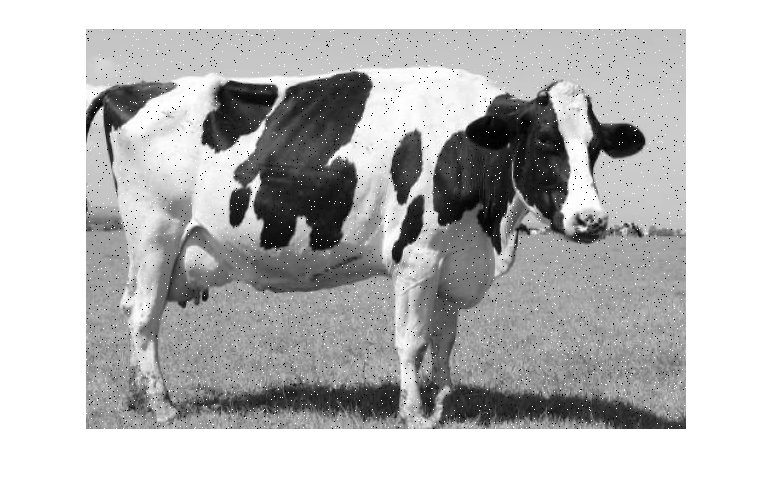

imshow(I, []);

Imagen filtrada:

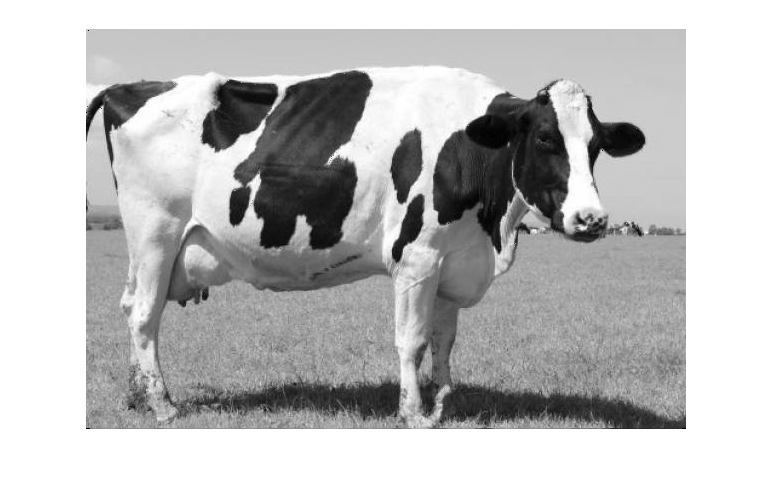

F = colfilt(I, [9 9], 'sliding', @Ejercicio_2);
imshow(F, []);